clf; hold on;
n=20;

a=poly(1:n) % generare polinom cu coef dati

a = 	1.0e+19 *

    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0010    0.0063   -0.0311    0.1207   -0.3600    0.8038   -1.2871    1.3804   -0.8753    0.2433


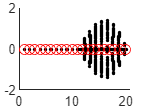

 for i=1:100
   vect = randn(1,n+1) * 1e-10;
   ap = a+vect;
   r=roots(ap);
   plot(real(r),imag(r),'.k');
 
 end
 plot(1:n,zeros(1,n),'or');
 xlim([0 n+1]);

% Studiem conditionarea pentru a^k = 2^-k
poli2 = 2.^-(1:20);
numar_conditionare=condpol(poli2)

numar_conditionare =     0.0001    0.0002    0.0005    0.0010    0.0020    0.0039    0.0078    0.0156    0.0312    0.0624    0.1249    0.2497    0.4994    0.9988    1.9976    3.9953    7.9906   15.9811   31.9623   63.9245
    0.0001    0.0002    0.0005    0.0010    0.0020    0.0039    0.0078    0.0156    0.0312    0.0624    0.1249    0.2497    0.4994    0.9988    1.9976    3.9953    7.9906   15.9811   31.9623   63.9245
    0.0001    0.0001    0.0002    0.0005    0.0010    0.0020    0.0040    0.0079    0.0158    0.0316    0.0632    0.1264    0.2528    0.5056    1.0113    2.0225    4.0451    8.0902   16.1803   32.3607
    0.0001    0.0001    0.0002    0.0005    0.0010    0.0020    0.0040    0.0079    0.0158    0.0316    0.0632    0.1264    0.2528    0.5056    1.0113    2.0225    4.0451    8.0902   16.1803   32.3607
    0.0000    0.0001    0.0002    0.0003    0.0007    0.0013    0.0027    0.0054    0.0108    0.0215    0.0430    0.0860    0.1721    0.3442    0.6883    1.3767    2.7534    5

r2 = roots(poli2);

figure(2)
nn=length(r2);
h=plot(r2,zeros(1,nn),'k.');

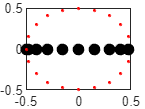

set(h,'Markersize',21);
hold on

for i=1:20
    % distributie normala
    poli1_per_norm = poli2 + normrnd(0, 1e-10, 1, length(poli2));
    r_norm = roots(poli1_per_norm);
    h2=plot(r_norm,'b.');
    hold on
    set(h2,'Markersize',4)
    
    % distributie uniforma
    poli1_per_unif = poli2 + unifrnd(0, 1e-10, 1, length(poli2));
    r_unif = roots(poli1_per_unif);
    h3=plot(r_unif,'r*');
    hold on
    set(h3,'Markersize',2)
end
hold off

%function nc = condpol(p,r)
% conditionarea unei ecuatii polinomiale p(x)=0
% p polinom de forma '[...]'
% r radacinile polinomului de forma '[...]'

 %   if nargin<2
 %       r = roots(p);
 %   end
    
    % calculam derivata p'(x)
    % derivata are cu 1 mai putini termeni in polinomul asociat
  %  n = length(p)-1;                  
  %  dp = [n:-1:1] .* p(1:end-1); %derivata;
  %  val_df = polyval(dp,r); % calculam val derivatei in fiecare radacina
  %  poliv = polyval(abs(p(2:end)),abs(r));
    % nc = poliv./(abs(r.*val_df));
  %  nc = abs(val_df.*r)./poliv
%end
function nc = condpol(p,r)
    if nargin < 2
        r = roots(p);
    end
    
    % Compute the derivative p'(x)
    dp = polyder(p);
    
    % Calculate the value of the derivative at each root
    val_df = polyval(dp, r);
    
    % Calculate the absolute values of the polynomial's coefficients
    abs_p = abs(p);
    
    % Calculate the condition number
    nc = abs(val_df .* r) ./ abs_p;
end